set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

# Part 3: SETAR(2;1;1) with cumulated conditional mean


%% Simulate data 
rng default

% --- Model parameters ---
phi10 = 1;   phi11 = 0.6;    % Regime 1
phi20 = -1; phi21 = 0.4;   % Regime 2
r     = 0;                   % threshold
sigma = 1.0;                 % noise std

% --- Simulate with burn-in ---
N = 1000; B = 300; T = N + B;
e = sigma * randn(T,1);
X = zeros(T,1); 
X(1) = 0;

for t = 2:T
    if X(t-1) <= r
        X(t) = phi10 + phi11 * X(t-1) + e(t);
    else
        X(t) = phi20 + phi21 * X(t-1) + e(t);
    end
end

M_true = @(x) (phi10 + phi11*x) .* (x <= r) + (phi20 + phi21*x) .* (x > r);

X = X(B+1:end);
xt = X(1:end-1);
yt = X(2:end);

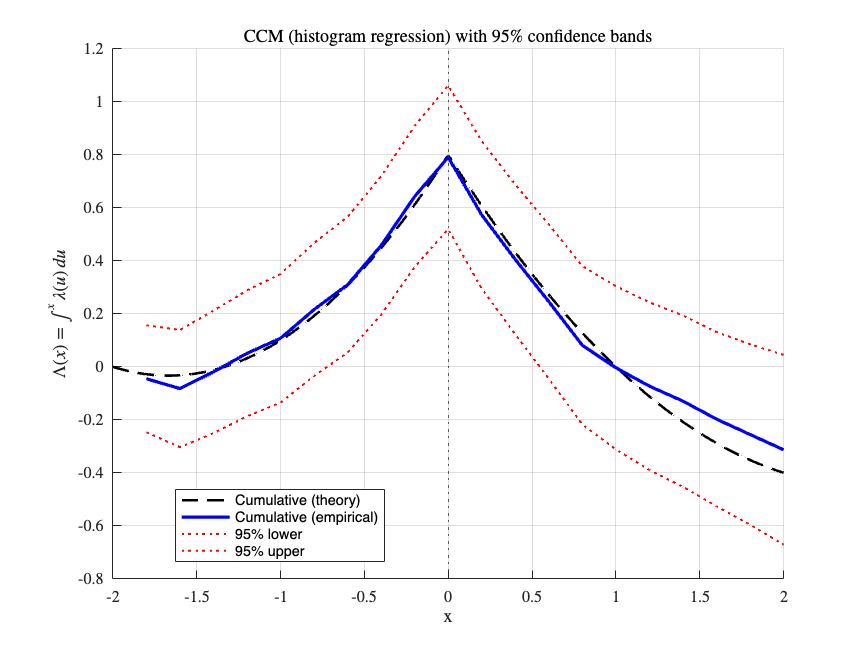

%% --- CCM via textbook histogram regression (regressogram) ---

% 1) Histogram regression parameters 
bin    = [-2 2];
n_bin  = 20;
h      = (bin(2) - bin(1)) / n_bin;
bin_pts = (bin(1)+h/2) : h : (bin(2)-h/2);   % midpoints

% 2) Binwise estimates of lambda (cond. mean), gamma (cond. var), and f(x)
lambda = zeros(n_bin,1);
gamma  = zeros(n_bin,1);
f_hat  = zeros(n_bin,1);

cur_bin = [bin_pts(1) - 0.5*h, bin_pts(1) + 0.5*h];
for i = 1:n_bin
    idx = (xt > cur_bin(1)) & (xt <= cur_bin(2));
    cnt = sum(idx);
    if cnt > 5
        yi = yt(idx);
        lambda(i) = sum(yi) / cnt;                         % E[Y | X in bin]
        f_hat(i)  = (n_bin*h)^(-1) * cnt;                  % histogram density proxy
        gamma(i)  = sum((yi - lambda(i)).^2) / cnt;        % Var[Y | X in bin]
    else
        fprintf('Need more points in bin %d\n', i);
        break
    end
    cur_bin = cur_bin + h;  % move to next bin
end

% 3) Cumulative functions and 95% confidence bands (Eq. (3.10))
c = 1.273;                              % 95% band constant (Table 3.1)
x = linspace(bin(1), bin(2), 300);

Lambda = cumsum(lambda * h);            % \hat{\Lambda}(x) = \int \hat{\lambda}
h_hat  = gamma ./ f_hat;                % \hat{h}(x) = \hat{\gamma}(x)/\hat{f}(x)
H_hat  = cumsum(h_hat * h);             % \hat{H}(x) = \int \hat{\gamma}/\hat{f}
H_hat_b = H_hat(n_bin);

Lambda_lower = Lambda - c .* n_bin^(-0.5) .* sqrt(H_hat_b) .* (1 + H_hat/H_hat_b);
Lambda_upper = Lambda + c .* n_bin^(-0.5) .* sqrt(H_hat_b) .* (1 + H_hat/H_hat_b);

% 4) (Optional) theoretical cumulative from your M_true on the same bin grid
Lambda_true = cumtrapz(x, M_true(x));

% 5) Plot (as in the example)
figure('Name','CCM (histogram regression) with 95% bands','Color','w'); hold on; grid on
plot(x, Lambda_true, 'k--', 'LineWidth', 1.6);           % optional theory
plot(bin_pts+0.5*h, Lambda,      'b-',  'LineWidth', 2.0);
plot(bin_pts+0.5*h, Lambda_lower,'r:',  'LineWidth', 1.2);
plot(bin_pts+0.5*h, Lambda_upper,'r:',  'LineWidth', 1.2);
xline(0, ':');

xlabel('x');
set(gca,'TickLabelInterpreter','latex');
ylabel('$\Lambda(x)=\int^{x} \lambda(u)\,du$','Interpreter','latex');
title('CCM (histogram regression) with 95\% confidence bands', ...
      'Interpreter','latex');
legend({'Cumulative (theory)','Cumulative (empirical)','95% lower','95% upper'}, ...
       'Location','best','Interpreter','none');

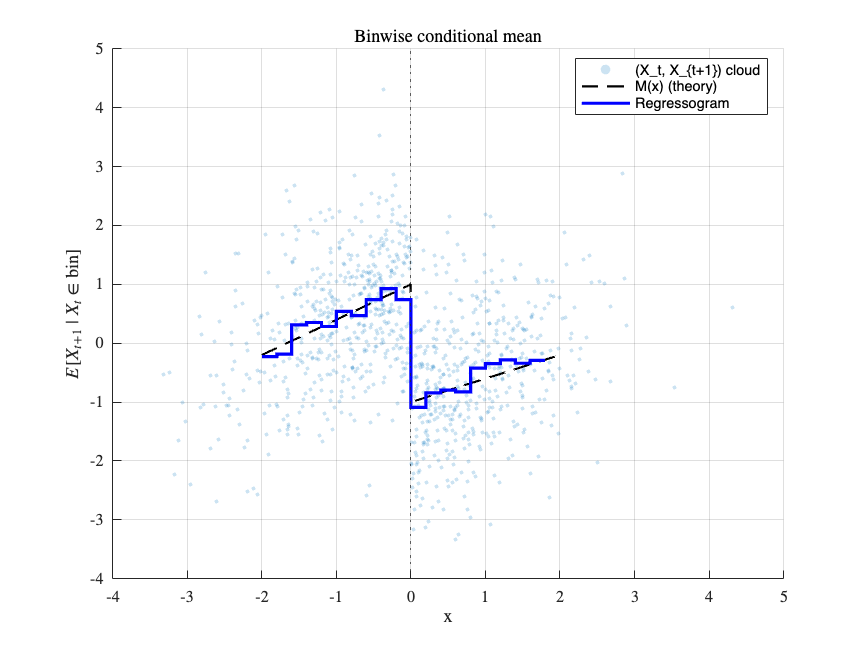

%% --- Plot binwise conditional mean (regressogram) ---
bin_edges = linspace(bin(1), bin(2), n_bin+1);

figure('Name','Binwise conditional mean (regressogram)','Color','w'); hold on; grid on
% raw cloud (light)
scatter(xt, yt, 6, 'filled', 'MarkerFaceAlpha', 0.20, 'MarkerEdgeAlpha', 0.05);

% true conditional mean for reference (optional)
x_fine = linspace(bin(1), bin(2), 400);
plot(x_fine, M_true(x_fine), 'k--', 'LineWidth', 1.4);

% regressogram = piecewise-constant per bin
stairs(bin_edges(1:end-1), lambda, 'b-', 'LineWidth', 2);  % step at left edges
% mark bin midpoints and values
%plot(bin_pts, lambda, 'bo', 'MarkerFaceColor','b', 'MarkerSize', 4);

xline(0, ':');
xlabel('x');
ylabel('$E[X_{t+1}\mid X_t \in \mathrm{bin}]$','Interpreter','latex');
title('Binwise conditional mean');
legend({'(X_t, X_{t+1}) cloud','M(x) (theory)','Regressogram'}, ...
       'Location','best','Interpreter','none');

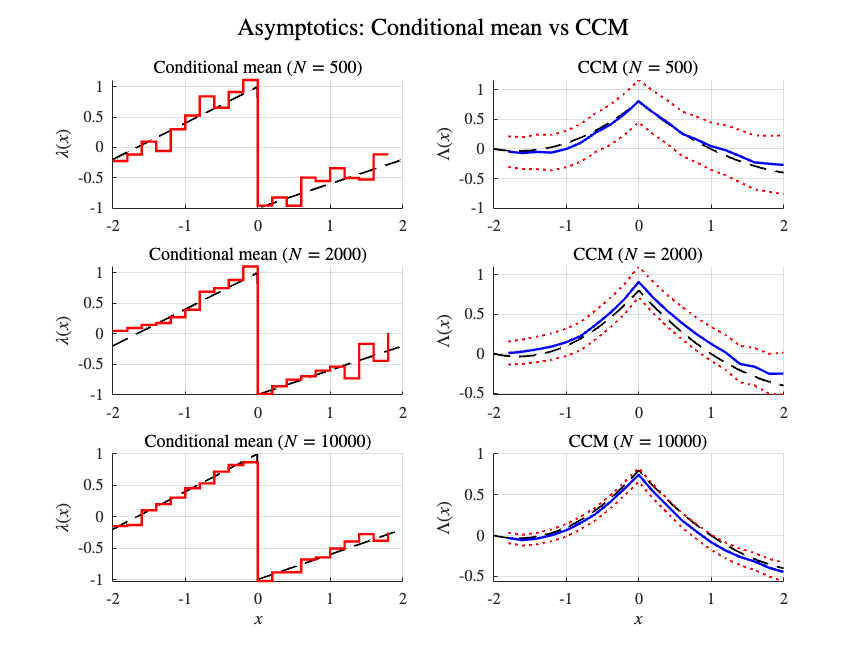

%% --- Compare asymptotic behaviour: Conditional mean vs CCM ---

sample_sizes = [500, 2000, 10000];  % try increasing N
n_bin = 20; 
bin    = [-2 2];
h      = (bin(2)-bin(1))/n_bin;
bin_pts = (bin(1)+h/2):h:(bin(2)-h/2);

figure('Name','Asymptotics: Conditional mean vs CCM','Color','w');
sgtitle('Asymptotics: Conditional mean vs CCM')

for k = 1:numel(sample_sizes)
    Nk = sample_sizes(k);
    
    B = 300; T = Nk + B;
    e = sigma * randn(T,1);
    X = zeros(T,1); 
    X(1) = 0;
    
    for t = 2:T
        if X(t-1) <= r
            X(t) = phi10 + phi11 * X(t-1) + e(t);
        else
            X(t) = phi20 + phi21 * X(t-1) + e(t);
        end
    end
        
    X = X(B+1:end);
    % simulate shorter series
    xt = X(1:end-1);
    yt = X(2:end);

    % binwise regression
    lambda = nan(n_bin,1);
    cur_bin = [bin_pts(1)-0.5*h, bin_pts(1)+0.5*h];
    for i=1:n_bin
        idx = (xt > cur_bin(1)) & (xt <= cur_bin(2));
        cnt = sum(idx);
        if cnt > 5
            yi = yt(idx);
            lambda(i) = sum(yi) / cnt;                         % E[Y | X in bin]
            f_hat(i)  = (n_bin*h)^(-1) * cnt;                  % histogram density proxy
            gamma(i)  = sum((yi - lambda(i)).^2) / cnt;        % Var[Y | X in bin]
        else
            fprintf('Need more points in bin %d\n', i);
            break
        end
        cur_bin = cur_bin + h;  % move to next bin
    end
    c = 1.273;  
    x = linspace(bin(1), bin(2), 300);

    % cumulative
    Lambda = cumsum(lambda * h);

    h_hat  = gamma ./ f_hat;                % \hat{h}(x) = \hat{\gamma}(x)/\hat{f}(x)
    H_hat  = cumsum(h_hat * h);             % \hat{H}(x) = \int \hat{\gamma}/\hat{f}
    H_hat_b = H_hat(n_bin);
    
    Lambda_lower = Lambda - c .* n_bin^(-0.5) .* sqrt(H_hat_b) .* (1 + H_hat/H_hat_b);
    Lambda_upper = Lambda + c .* n_bin^(-0.5) .* sqrt(H_hat_b) .* (1 + H_hat/H_hat_b);

    % plot side by side
    subplot(numel(sample_sizes),2,2*k-1); hold on; grid on
    plot(x, M_true(x), 'k--','LineWidth',1.2);
    stairs(bin_pts-0.5*h, lambda, 'r-','LineWidth',1.5);
    title(sprintf('Conditional mean ($N=%d$)', Nk), 'Interpreter','latex');
    if k == numel(sample_sizes)
        xlabel('$x$', 'Interpreter','latex'); 
    end
    ylabel('$\lambda(x)$', 'Interpreter','latex');
    
    subplot(numel(sample_sizes),2,2*k); hold on; grid on
    plot(x, cumtrapz(x,M_true(x)), 'k--','LineWidth',1.2);
    plot(bin_pts+0.5*h, Lambda, 'b-','LineWidth',1.5);
    plot(bin_pts+0.5*h, Lambda_lower,'r:',  'LineWidth', 1.2);
    plot(bin_pts+0.5*h, Lambda_upper,'r:',  'LineWidth', 1.2);
    title(sprintf('CCM ($N=%d$)', Nk), 'Interpreter','latex');
    if k == numel(sample_sizes)
        xlabel('$x$', 'Interpreter','latex'); 
    end 
    ylabel('$\Lambda(x)$', 'Interpreter','latex');
end

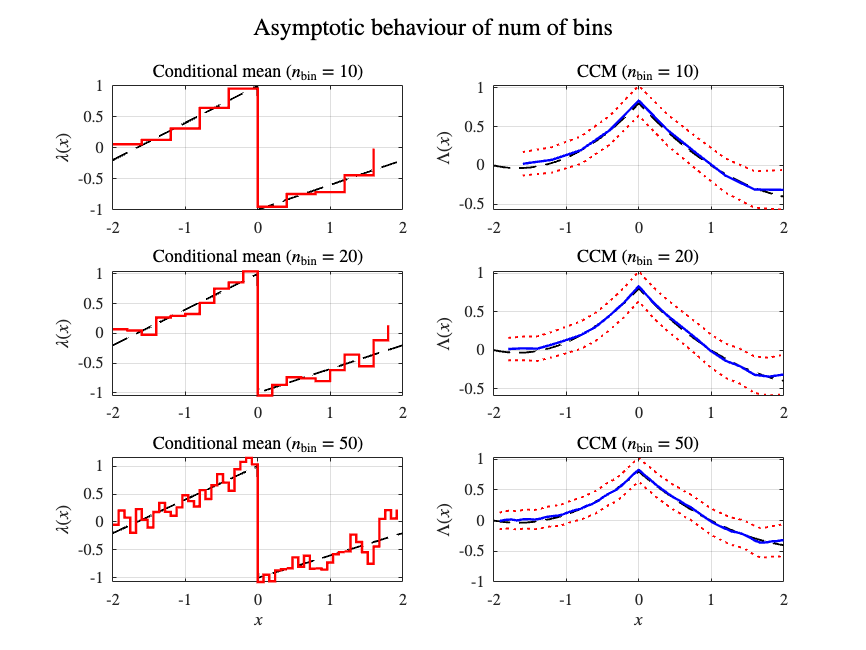

%% --- Compare asymptotic behaviour: Conditional mean vs CCM (vary bins) ---
% Assumes you already defined: phi10, phi11, phi20, phi21, r, sigma, and M_true(x).

set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

bins_list = [10, 20, 50];     % <— vary bins instead of N
Nk        = 2000;             % fixed sample size
bin       = [-2 2];
c         = 1.273;            % asymptotic 95% band constant
x         = linspace(bin(1), bin(2), 300);

figure('Name','Asymptotics: Conditional mean vs CCM (vary bins)','Color','w');
sgtitle('Asymptotic behaviour of num of bins');

% ----- simulate once (fixed N) -----
B = 300; T = Nk + B;
e = sigma * randn(T,1);
X = zeros(T,1); X(1) = 0;
for t = 2:T
    if X(t-1) <= r
        X(t) = phi10 + phi11 * X(t-1) + e(t);
    else
        X(t) = phi20 + phi21 * X(t-1) + e(t);
    end
end
X  = X(B+1:end);
xt = X(1:end-1);
yt = X(2:end);

for k = 1:numel(bins_list)
    n_bin = bins_list(k);
    h     = (bin(2)-bin(1))/n_bin;
    bin_pts = (bin(1)+h/2):h:(bin(2)-h/2);   % midpoints

    % --- binwise regression ---
    lambda = nan(n_bin,1);
    gamma  = nan(n_bin,1);
    f_hat  = nan(n_bin,1);

    cur_bin = [bin_pts(1)-0.5*h, bin_pts(1)+0.5*h];
    for i=1:n_bin
        idx = (xt > cur_bin(1)) & (xt <= cur_bin(2));
        cnt = sum(idx);
        if cnt > 5
            yi       = yt(idx);
            lambda(i)= sum(yi) / cnt;                   % E[Y|X in bin]
            f_hat(i) = (n_bin*h)^(-1) * cnt;            % histogram density proxy
            gamma(i) = sum((yi - lambda(i)).^2) / cnt;  % Var[Y|X in bin]
        else
            warning('Need more points in bin %d (cnt=%d).', i, cnt);
        end
        cur_bin = cur_bin + h;  % move to next bin
    end

    % --- cumulative & confidence bands ---
    Lambda  = cumsum(lambda * h);          % \hat{\Lambda}(x)
    h_hat   = gamma ./ f_hat;              % \hat{h}(x) = \hat{\gamma}/\hat{f}
    H_hat   = cumsum(h_hat * h);           % \hat{H}(x) = \int \hat{\gamma}/\hat{f}
    H_hat_b = H_hat(end);                  % value at right boundary

    % 95% bands (same formula as before)
    band_fac      = c .* n_bin^(-0.5) .* sqrt(H_hat_b);
    Lambda_lower  = Lambda - band_fac .* (1 + H_hat/H_hat_b);
    Lambda_upper  = Lambda + band_fac .* (1 + H_hat/H_hat_b);

    % Left column
    subplot(numel(bins_list),2,2*k-1); hold on; grid on; box on
    plot(x, M_true(x), 'k--','LineWidth',1.2);
    stairs(bin_pts-0.5*h, lambda, 'r-','LineWidth',1.5);
    title(sprintf('Conditional mean ($n_{\\mathrm{bin}}=%d$)', n_bin), 'Interpreter','latex');
    if k == numel(bins_list), xlabel('$x$','Interpreter','latex'); end
    ylabel('$\lambda(x)$','Interpreter','latex');
    
    % Right column
    subplot(numel(bins_list),2,2*k); hold on; grid on; box on
    plot(x, cumtrapz(x, M_true(x)), 'k--','LineWidth',1.2);
    plot(bin_pts+0.5*h, Lambda, 'b-','LineWidth',1.5);
    plot(bin_pts+0.5*h, Lambda_lower,'r:', 'LineWidth',1.2);
    plot(bin_pts+0.5*h, Lambda_upper,'r:', 'LineWidth',1.2);
    title(sprintf('CCM ($n_{\\mathrm{bin}}=%d$)', n_bin), 'Interpreter','latex');
    if k == numel(bins_list), xlabel('$x$','Interpreter','latex'); end
    ylabel('$\Lambda(x)$','Interpreter','latex');
end